**Q1. Pick one of the stocks from data set 1 and compute the natural logarithm of the price series for this stock. Use the Box-Jenkins methodology to estimate an appropriate time series model for the log-price series and investigate the forecasting ability of the model.**

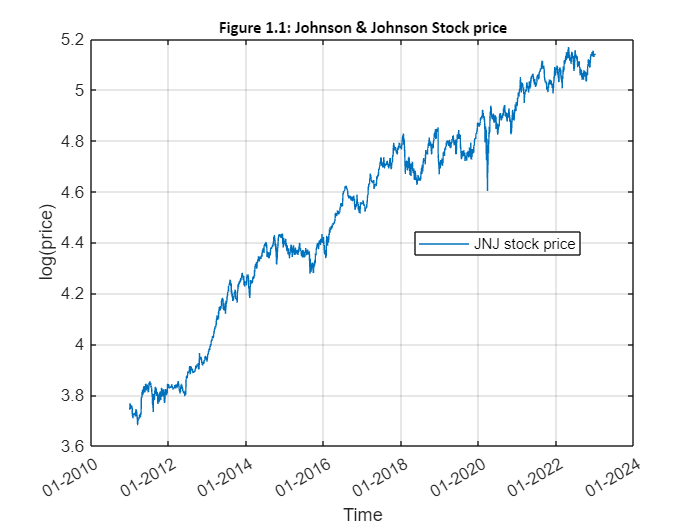

%Task 1

%Setting default directory
cd('Set location of your default directory');

%Set file location for loading data 1
file_location = 'Your file location\Data set 1';
[jnj_price, date] = log_pop(file_location, 'JNJ.xlsx', 'JNJ', 'F2:F3022');

% Displaying the sstock log price over the years
plot(date,jnj_price);
grid on;
title("Figure 1.1: Johnson & Johnson Stock price", ...
    FontSize=10,FontName="Calibri"); % Adding a title
legend("JNJ stock price", Location="best"); % Adding legend
xlabel("Time");
ylabel("log(price)");
datetick('x','mm-yyyy') %Add date ticks.

% Saving the current graph
% saveas(gcf,"fig11.jpg"); % Uncomment to save the graph


% Getting descriptive statistics of the data using user defined function
stat = desc_stat(jnj_price);

% Displaying the calculated data
for i=1:size(stat,1)
        fprintf("%s: %f \n",stat(i,1), stat(i,2));
end

Minimum: 3.681800 
1st Quartile: 4.248800 
Median: 4.587900 
Mean: 4.520300 
3rd Quartile: 4.833600 
Maximum: 5.168800 
Standard Deviation: 0.412590 
Variance: 0.170230 
Kurtosis: 2.060600 
Skewness: -0.388730 


% Saving the stat array in an excel format
% writematrix(stat,"Task 1 descriptive statistics.xlsx"); %Table 1.1(Uncomment to save)

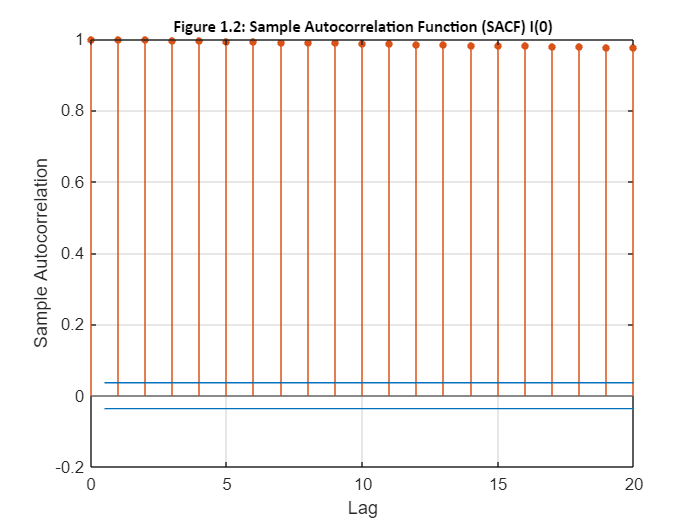


% Step 1: Model identification

% Plotting SACF of log price(jnj_price)
autocorr(jnj_price);
title("Figure 1.2: Sample Autocorrelation Function (SACF) I(0)", ...
    FontSize=10,FontName="Calibri");


% Saving the current graph
% saveas(gcf,"fig12.png"); % Uncomment to save the graph
% Creating an array with first row as headers and next row as its
% corresponding values
adf_test1(1,1) = "p-Value"; adf_test1(1,2) = "t statistic"; adf_test1(1,3) = "Critical Value";
% Computing the ADF test.
[h,adf_test1(2,1),adf_test1(2,2),adf_test1(2,3),~] = adftest(jnj_price,'model','AR','test','t1','alpha',0.05);
% Saving the ADF test in an excel format
% writematrix(adf_test1,"Task 1 ADF test 1.xlsx"); %Table 1.2(Uncomment to save)

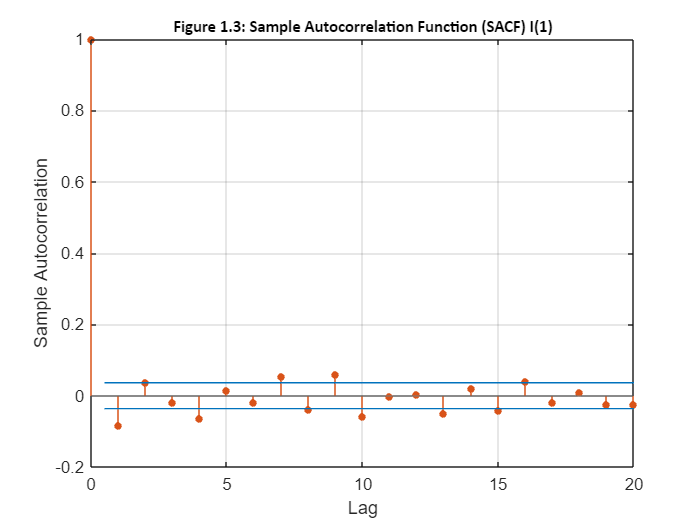

%Now let us take first difference of the data I(1)
djnj_price = jnj_price(2:end,1)-jnj_price(1:end-1,1);
autocorr(djnj_price);
title("Figure 1.3: Sample Autocorrelation Function (SACF) I(1)", ...
    FontSize=10,FontName="Calibri");


% Saving the current graph
% saveas(gcf,"fig13.jpg"); % Uncomment to save the graph
% Creating an array with first row as headers and next row as its
% corresponding values
adf_test2(1,1) = "p-Value"; adf_test2(1,2) = "t statistic"; adf_test2(1,3) = "Critical Value";
% Computing the DF test.
[h,adf_test2(2,1),adf_test2(2,2),adf_test2(2,3),~] = adftest(djnj_price,'model','AR','test','t1','alpha',0.01);
% Saving the ADF test in an excel format
% writematrix(adf_test2,"Task 1 ADF test 2.xlsx"); %Table 1.3(Uncomment to save)

%To determine values of p and q in AR(p) and MA(q) BIC will be used.

% Using User defined bic_test function to get optimal value of p and q
[eff_p,eff_q,bic1,minValue1] = bic_test(jnj_price,4,4); % check BIC value till ARIMA(4,1,4)

% % Saving the BIC values in an excel format
% writematrix(bic1,"Task 1 BIC test 1.xlsx"); %Table 1.4(Uncomment to save)

% Step 2: Model Estimation
% Defining 90% i.e. 2719 as the training sample
train_n = 2719;
% Checking the optimal value of p and q for training sample
[opt_p,opt_q,bic,minValue] = bic_test(jnj_price(1:train_n,1),4,4);

% As we can see the p and q values are the same for training set 
% Creating an ARIMA(p,d,q) model.
opt_mdl = arima(opt_p,1,opt_q);

% Estimating by Maximum Likelihood approach
opt_fit= estimate(opt_mdl, jnj_price(1:train_n,1));

 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00051143     0.00021665        2.3606        0.018244
    AR{1}          -0.0853      0.0088538       -9.6343      5.7262e-22
    Variance    0.00011595     1.2776e-06        90.754               0



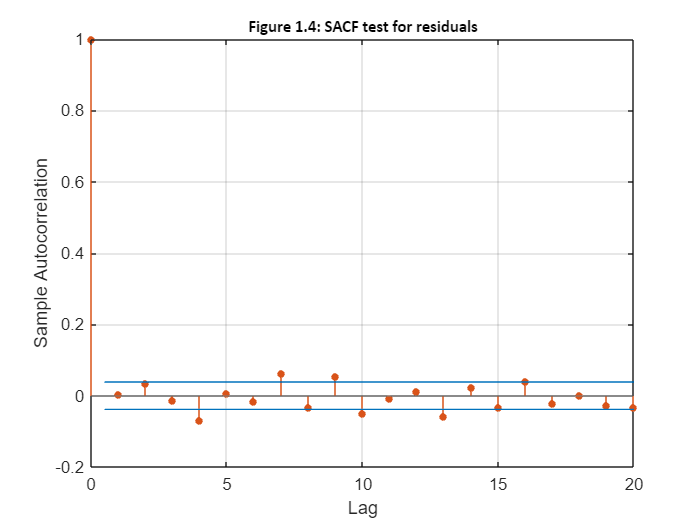

% Step 3: Diagnostic Testing
% Computing the residual
[residual, var] = infer(opt_fit,jnj_price(1:train_n,1));

% Standardizing the residual
stdr = residual/sqrt(opt_fit.Variance);
autocorr(stdr);
title("Figure 1.4: SACF test for residuals", ...
    FontSize=10,FontName="Calibri");


% Saving the current graph
% saveas(gcf,"fig14.jpg"); % Uncomment to save the graph

% Forecasting (iterated multi period forecasting)
train_price = zeros(size(jnj_price,1),1);
train_price(1:train_n,1) = jnj_price(1:train_n,1);
for i=train_n:size(jnj_price,1)-1
    % After every iteration incorporating the forecasted value
    est_fit = estimate(opt_mdl, train_price(1:i,1),'Display','off');
    %Computing the forecasts.
    [train_price(i+1,1),~] = forecast(est_fit,1,train_price(1:i,1));
end

% Computing MSE using User defined function mse_cal
mse = mse_cal(jnj_price(train_n+1:end,1),train_price(train_n+1:end,1));
    
plot(date(train_n+1:end,1),train_price(train_n+1:end,1),'b', LineWidth=1.5); %Plot the forecasts.
hold on %Add additional elements to the plot.
plot(date(train_n+1:end,1),jnj_price(train_n+1:end,1),Color=[0.5,0.5,0.5], LineWidth=0.5); %Plot the actual values.
plot(date(train_n+1:end,1),train_price(train_n+1:end,1) +  1.96*sqrt(mse),'r-.');%, LineWidth=0.5);
plot(date(train_n+1:end,1),train_price(train_n+1:end,1) -  1.96*sqrt(mse),'r-.')%, LineWidth=0.5);

legend('Forecast','Actual values','95% confidence interval' ...
    ,Location='best'); %Adding the legend.
title('Figure 1.5: JNJ forecasts for the last 302 trading days of the dataset', ...
    FontSize=10,FontName="Calibri"); %Adding a title.
datetick('x','mm-yyyy'); %Adding date ticks.
hold off %Closing the hold on function.
% Saving the current graph
% saveas(gcf,"fig15.jpg"); % Uncomment to save the graph
% Plotting the MSE
plot(1:302,mse);
title('Figure 1.6: Mean Squared Error over Days', ...
    FontSize=10,FontName="Calibri");
xlabel("Days");
ylabel("Mean Squared Error");
% Saving the current graph
% saveas(gcf,"fig16.jpg"); % Uncomment to save the graph